# Week 13

Exercise 3


clear
close all


Part a

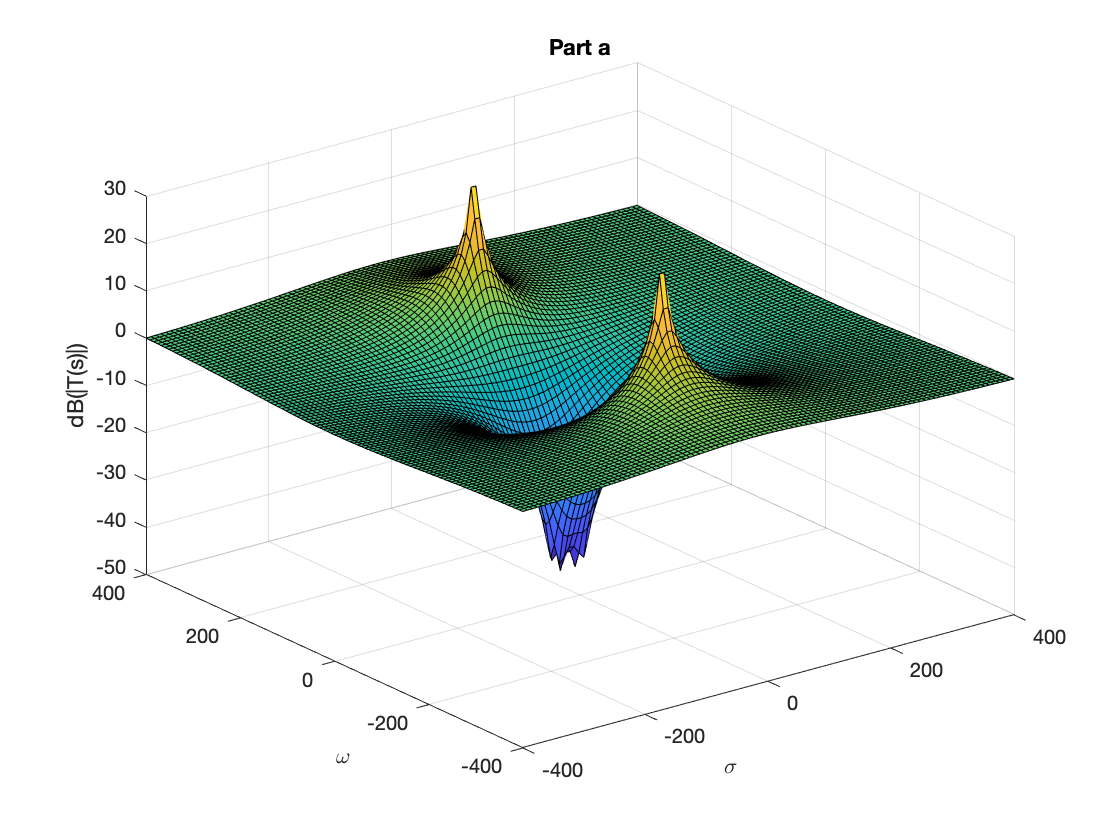



R = 100;
C = 10e-6;
L = 2.5;


sigma = linspace(-400, 400, 101);
omega = linspace(-400, 400, 101);
s = sigma + 1j*omega';
T2 = @(s) (L*C*s.^2+R*C*s)./(L*C*s.^2+R*C*s+1);
surf(sigma, omega, db(abs(T2(s))));
title("Part a")
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

Part b

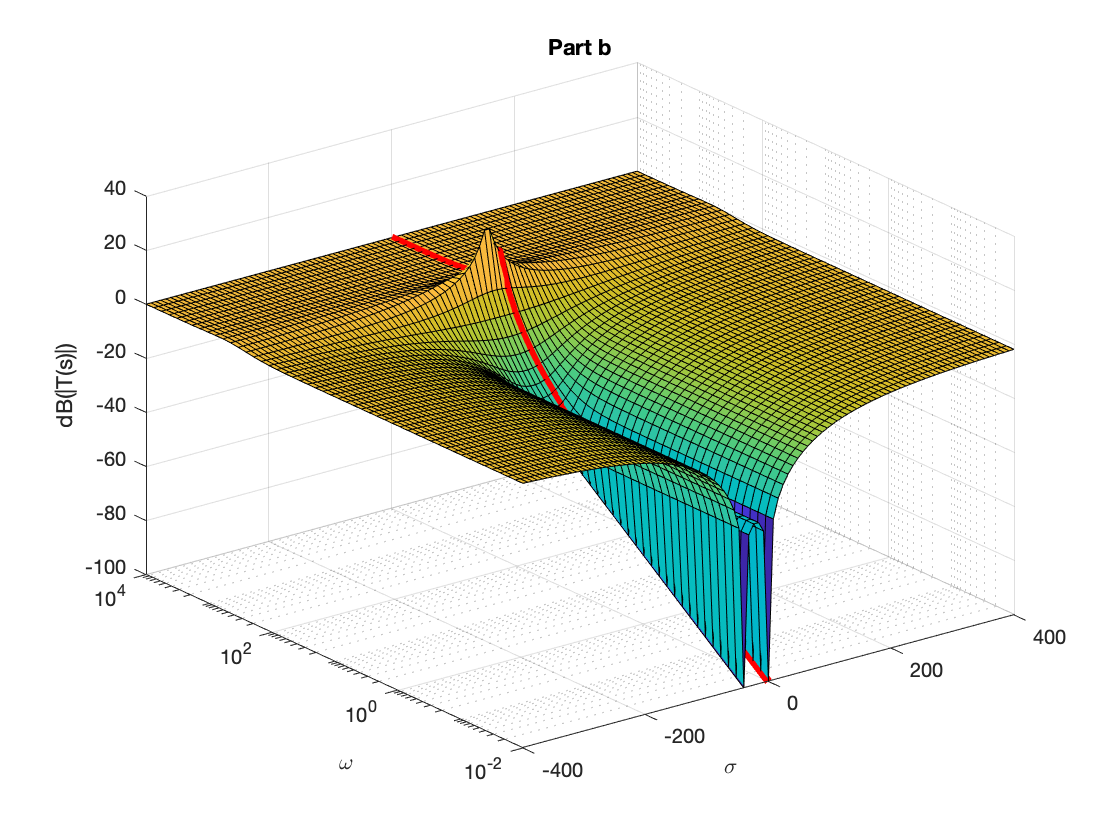


omega = logspace(-2, 4);
s = sigma + 1j*omega';
surf(sigma,omega,db(abs(T2(s))))
title("Part b")
set(gca, 'YScale', 'log');
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

sigma = 0 * omega;
s = sigma + 1j*omega';
hold on
plot3(sigma,omega,db(abs(T2(s))), 'r', 'LineWidth', 4)
hold off

Part c

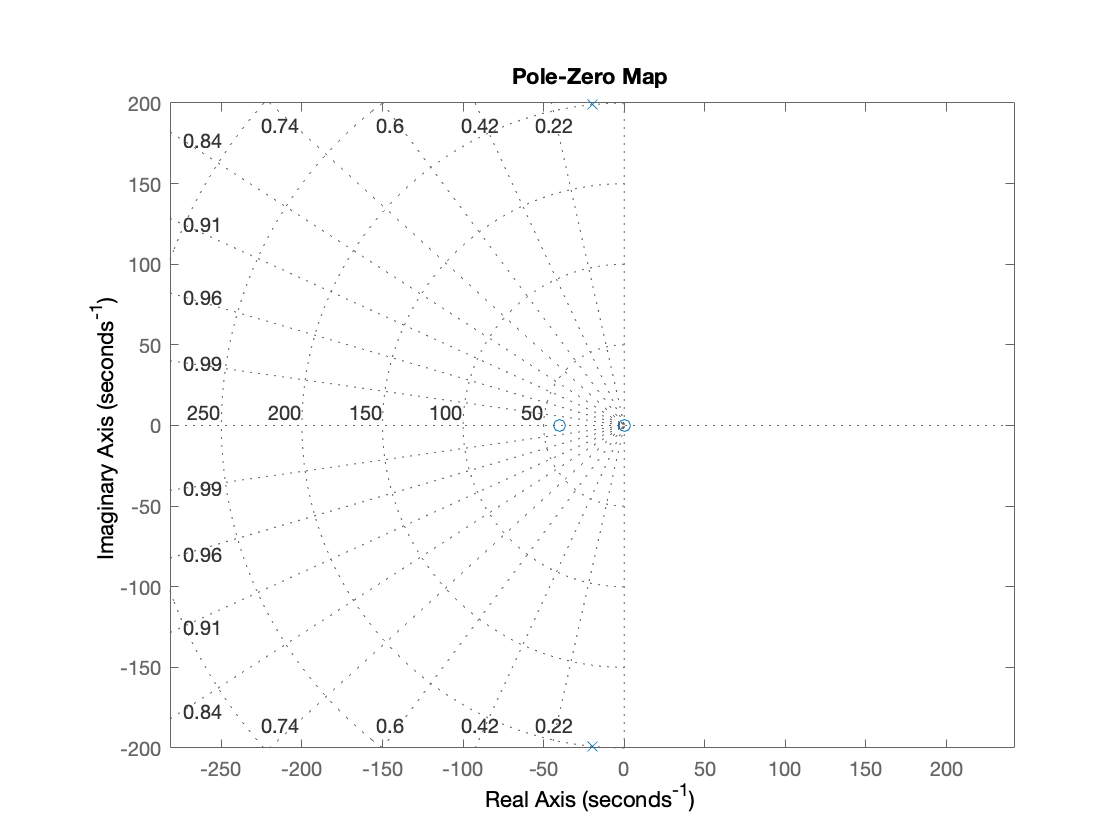


s = tf('s');
T = (L*C*s^2+R*C*s)/(L*C*s^2+R*C*s+1);
pzmap(T)
grid on
axis equal

Part d

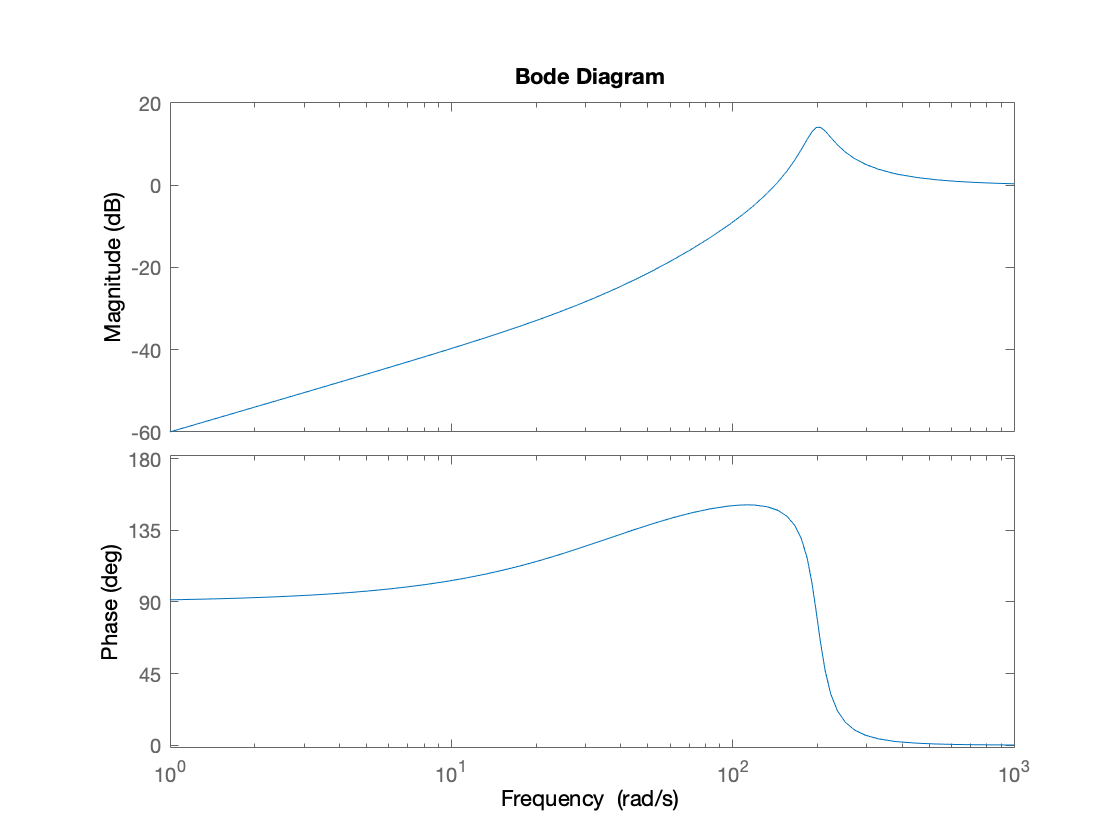


bode(T)